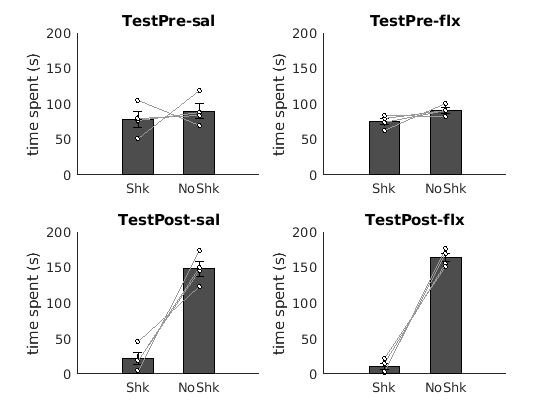

%% Look at effect of conditionning
figure
clear ZoneTime AllDat
Files=PathForExperimentsEmbReact('TestPre_PreDrug');
for mm=1:length(Files.path)
    for c=1:4
        cd(Files.path{mm}{c})
        load('behavResources_SB.mat')
        load('ExpeInfo.mat')
        for k=1:5
            Behav.ZoneEpoch{k}=Behav.ZoneEpoch{k};
            ZoneTime{c}(mm,k)=sum(Stop(Behav.ZoneEpoch{k},'s')-Start(Behav.ZoneEpoch{k},'s'));%./sum(sum(Zone{k}));
        end
    end
                Inj(mm) = double(strcmp(ExpeInfo.DrugInjected,'FLX'))+double(strcmp(ExpeInfo.DrugInjected,'FLX-Ineff'))*4;
end

AllDat=[];
for c=1:4
    AllDat=[AllDat;(ZoneTime{c}(:,:)')];
end
subplot(221)
PlotErrorBarN([mean(AllDat(1:5:end,Inj==0)+AllDat(4:5:end,Inj==0));mean(AllDat(2:5:end,Inj==0)+AllDat(5:5:end,Inj==0))]',0,1);
title('TestPre-sal'), ylabel('time spent (s)')
set(gca,'XTick',[1:2],'XTickLabel',{'Shk','NoShk'})
ylim([0 200])

subplot(222)
PlotErrorBarN([mean(AllDat(1:5:end,Inj==1)+AllDat(4:5:end,Inj==1));mean(AllDat(2:5:end,Inj==1)+AllDat(5:5:end,Inj==1))]',0,1);
title('TestPre-flx'), ylabel('time spent (s)')
set(gca,'XTick',[1:2],'XTickLabel',{'Shk','NoShk'})
ylim([0 200])

clear ZoneTime AllDat
Files=PathForExperimentsEmbReact('TestPost_PostDrug');
for mm=1:length(Files.path)
    for c=1:4
        cd(Files.path{mm}{c})
        load('behavResources_SB.mat')
        load('ExpeInfo.mat')
        for k=1:5
            Behav.ZoneEpoch{k}=Behav.ZoneEpoch{k};
            ZoneTime{c}(mm,k)=sum(Stop(Behav.ZoneEpoch{k},'s')-Start(Behav.ZoneEpoch{k},'s'));%./sum(sum(Zone{k}));
        end
    end
                Inj(mm) = double(strcmp(ExpeInfo.DrugInjected,'FLX'))+double(strcmp(ExpeInfo.DrugInjected,'FLX-Ineff'))*4;
end

AllDat=[];
for c=1:4
    AllDat=[AllDat;(ZoneTime{c}(:,:)')];
end
subplot(223)
PlotErrorBarN([mean(AllDat(1:5:end,Inj==0)+AllDat(4:5:end,Inj==0));mean(AllDat(2:5:end,Inj==0)+AllDat(5:5:end,Inj==0))]',0,1);
title('TestPost-sal'), ylabel('time spent (s)')
set(gca,'XTick',[1:2],'XTickLabel',{'Shk','NoShk'})
ylim([0 200])

subplot(224)
PlotErrorBarN([mean(AllDat(1:5:end,Inj==1)+AllDat(4:5:end,Inj==1));mean(AllDat(2:5:end,Inj==1)+AllDat(5:5:end,Inj==1))]',0,1);
title('TestPost-flx'), ylabel('time spent (s)')
set(gca,'XTick',[1:2],'XTickLabel',{'Shk','NoShk'})
ylim([0 200])

Now we'll have a look at the behaviour when the animal is blocked

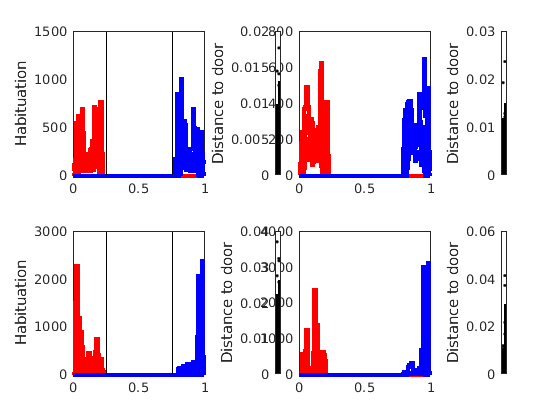

clear MeanDist Dist
figure
Files=PathForExperimentsEmbReact('HabituationBlockedShock_PreDrug');

for mm=1:length(Files.path)
    cd(Files.path{mm}{1})
    load('behavResources_SB.mat')
    load('ExpeInfo.mat')
                Inj(mm) = double(strcmp(ExpeInfo.DrugInjected,'FLX'))+double(strcmp(ExpeInfo.DrugInjected,'FLX-Ineff'))*4;
    Behav.LinearDist = Restrict(Behav.LinearDist,intervalSet(0,280*1e4));
    
    if strcmp(ExpeInfo.DrugInjected,'FLX')
        subplot(2,6,4:5)
        Dist.Shock{mm}=Data(Behav.LinearDist);
        [Y,X]=hist(Dist.Shock{mm},[0:0.01:1]);
        stairs(X,Y,'r','linewidth',3), hold on
    else
        subplot(2,6,1:2)
        Dist.Shock{mm}=Data(Behav.LinearDist);
        [Y,X]=hist(Dist.Shock{mm},[0:0.01:1]);
        stairs(X,Y,'r','linewidth',3), hold on
        
    end
    
    MeanDist.Shock(mm)=nanmean(Data(Behav.LinearDist)-Params.DoorPos(1)).^2;
    
end

Files=PathForExperimentsEmbReact('HabituationBlockedSafe_PreDrug');
for mm=1:length(Files.path)
    cd(Files.path{mm}{1})
    load('behavResources_SB.mat')
    load('ExpeInfo.mat')
    
    Behav.LinearDist = Restrict(Behav.LinearDist,intervalSet(0,280*1e4));
    
    if strcmp(ExpeInfo.DrugInjected,'FLX')
        subplot(2,6,4:5)
        Dist.Safe{mm}=Data(Behav.LinearDist);
        [Y,X]=hist(Dist.Safe{mm},[0:0.01:1]);
        stairs(X,Y,'b','linewidth',3), hold on
    else
        subplot(2,6,1:2)
        Dist.Safe{mm}=Data(Behav.LinearDist);
        [Y,X]=hist(Dist.Safe{mm},[0:0.01:1]);
        stairs(X,Y,'b','linewidth',3), hold on
        
    end
    MeanDist.Safe(mm)=nanmean(Data(Behav.LinearDist)-Params.DoorPos(2)).^2;
    
end
line([0.25 0.25],ylim,'color','k')
line([0.75 0.75],ylim,'color','k')
ylabel('Habituation')
Inj = double(Inj);
Inj(2) = 4;

subplot(2,6,3)
bar(2,nanmean(MeanDist.Safe(Inj==0)),'FaceColor',[0.6 0.6 1]), hold on
bar(1,nanmean(MeanDist.Shock(Inj==0)),'FaceColor',[1 0.6 0.6])
plotSpread({MeanDist.Shock(Inj==0);MeanDist.Safe(Inj==0)},'distributionColors',[ 0 0 0;0 0 0])
set(gca,'XTick',[1,2],'XTickLabel',{'Shk','NoShk'})
ylabel('Distance to door')
subplot(2,6,6)
bar(2,nanmean(MeanDist.Safe(Inj==1)),'FaceColor',[0.6 0.6 1]), hold on
bar(1,nanmean(MeanDist.Shock(Inj==1)),'FaceColor',[1 0.6 0.6])
plotSpread({MeanDist.Shock(Inj==1);MeanDist.Safe(Inj==1)},'distributionColors',[ 0 0 0;0 0 0])
set(gca,'XTick',[1,2],'XTickLabel',{'Shk','NoShk'})
ylabel('Distance to door')



Files=PathForExperimentsEmbReact('ExtinctionBlockedShock_PostDrug');

for mm=1:length(Files.path)
    cd(Files.path{mm}{1})
    load('behavResources_SB.mat')
    Behav.LinearDist = Restrict(Behav.LinearDist,intervalSet(0,280*1e4));
    load('ExpeInfo.mat')
    
    if strcmp(ExpeInfo.DrugInjected,'FLX')
        subplot(2,6,10:11)
        Dist.Shock{mm}=Data(Behav.LinearDist);
        [Y,X]=hist(Dist.Shock{mm},[0:0.01:1]);
        stairs(X,Y,'r','linewidth',3), hold on
    else
        subplot(2,6,7:8)
        Dist.Shock{mm}=Data(Behav.LinearDist);
        [Y,X]=hist(Dist.Shock{mm},[0:0.01:1]);
        stairs(X,Y,'r','linewidth',3), hold on
        
    end
    
    MeanDist.Shock(mm)=nanmean(Data(Behav.LinearDist)-Params.DoorPos(1)).^2;
    
end

Files=PathForExperimentsEmbReact('ExtinctionBlockedSafe_PostDrug');
for mm=1:length(Files.path)
    cd(Files.path{mm}{1})
    load('behavResources_SB.mat')
    Behav.LinearDist = Restrict(Behav.LinearDist,intervalSet(0,280*1e4));
    load('ExpeInfo.mat')
    
    if strcmp(ExpeInfo.DrugInjected,'FLX')
        subplot(2,6,10:11)
        Dist.Safe{mm}=Data(Behav.LinearDist);
        [Y,X]=hist(Dist.Safe{mm},[0:0.01:1]);
        stairs(X,Y,'b','linewidth',3), hold on
    else
        subplot(2,6,7:8)
        Dist.Safe{mm}=Data(Behav.LinearDist);
        [Y,X]=hist(Dist.Safe{mm},[0:0.01:1]);
        stairs(X,Y,'b','linewidth',3), hold on
        
    end
    MeanDist.Safe(mm)=nanmean(Data(Behav.LinearDist)-Params.DoorPos(2)).^2;
    
end
line([0.25 0.25],ylim,'color','k')
line([0.75 0.75],ylim,'color','k')
ylabel('Habituation')
Inj = double(Inj);
Inj(2) = 4;

subplot(2,6,9)
bar(2,nanmean(MeanDist.Safe(Inj==0)),'FaceColor',[0.6 0.6 1]), hold on
bar(1,nanmean(MeanDist.Shock(Inj==0)),'FaceColor',[1 0.6 0.6])
plotSpread({MeanDist.Shock(Inj==0);MeanDist.Safe(Inj==0)},'distributionColors',[ 0 0 0;0 0 0])
set(gca,'XTick',[1,2],'XTickLabel',{'Shk','NoShk'})
ylabel('Distance to door')
subplot(2,6,12)
bar(2,nanmean(MeanDist.Safe(Inj==1)),'FaceColor',[0.6 0.6 1]), hold on
bar(1,nanmean(MeanDist.Shock(Inj==1)),'FaceColor',[1 0.6 0.6])
plotSpread({MeanDist.Shock(Inj==1);MeanDist.Safe(Inj==1)},'distributionColors',[ 0 0 0;0 0 0])
set(gca,'XTick',[1,2],'XTickLabel',{'Shk','NoShk'})
ylabel('Distance to door')

Look at what's happening during conditionning

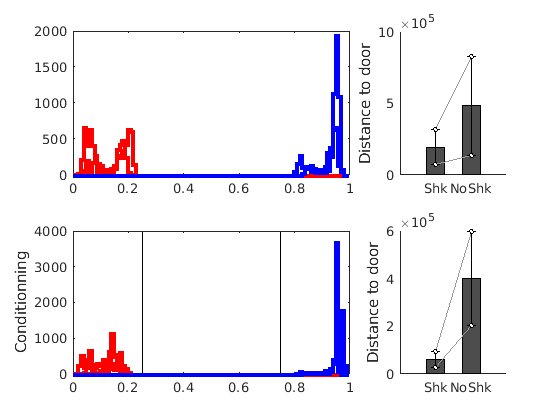

% Position when the door is closed and latency to escape
clear MeanDist Dist EscapeLat
DoorClosedEpoch=intervalSet(0,300*1e4);
figure
subplot(2,3,1:2)
Files=PathForExperimentsEmbReact('UMazeCondBlockedShock_PostDrug');

for mm=1:length(Files.path)
    for c=1:2
        cd(Files.path{mm}{c})
        load('behavResources_SB.mat')
        load('ExpeInfo.mat')
        
        Dist.Shock{mm,c}=Data(Restrict(Behav.LinearDist,DoorClosedEpoch));
        MeanDist.Shock(mm,c)=sum(Data(Restrict(Behav.LinearDist,DoorClosedEpoch))-Params.DoorPos(1)).^2;
        
        if strcmp(ExpeInfo.DrugInjected,'FLX')
            subplot(2,3,4:5)
            [Y,X]=hist(Dist.Shock{mm},[0:0.01:1]);
            stairs(X,Y,'r','linewidth',3), hold on
            
        else
            subplot(2,3,1:2)
            [Y,X]=hist(Dist.Shock{mm},[0:0.01:1]);
            stairs(X,Y,'r','linewidth',3), hold on
            
            
        end
         
         

    end
end
Files=PathForExperimentsEmbReact('UMazeCondBlockedSafe_PostDrug');

for mm=1:length(Files.path)
    for c=1:2
        cd(Files.path{mm}{c})
        load('behavResources_SB.mat')
                load('ExpeInfo.mat')

        Dist.Safe{mm,c}=Data(Restrict(Behav.LinearDist,DoorClosedEpoch));
        MeanDist.Safe(mm,c)=sum(Data(Restrict(Behav.LinearDist,DoorClosedEpoch))-Params.DoorPos(2)).^2;
        
         if strcmp(ExpeInfo.DrugInjected,'FLX')
            subplot(2,3,4:5)
            [Y,X]=hist(Dist.Safe{mm},[0:0.01:1]);
            stairs(X,Y,'b','linewidth',3), hold on
            
        else
            subplot(2,3,1:2)
            [Y,X]=hist(Dist.Safe{mm},[0:0.01:1]);
            stairs(X,Y,'b','linewidth',3), hold on
            
        end
         
    end
end
line([0.25 0.25],ylim,'color','k')
line([0.75 0.75],ylim,'color','k')
ylabel('Conditionning')
subplot(2,3,3)
PlotErrorBarN([mean(MeanDist.Shock(Inj==0,:)');mean(MeanDist.Safe(Inj==0,:)')]',0);
set(gca,'XTick',[1,2],'XTickLabel',{'Shk','NoShk'})
ylabel('Distance to door')
subplot(2,3,6)
PlotErrorBarN([mean(MeanDist.Shock(Inj==1,:)');mean(MeanDist.Safe(Inj==1,:)')]',0);
set(gca,'XTick',[1,2],'XTickLabel',{'Shk','NoShk'})
ylabel('Distance to door')

Now lets see where and how much the are freezing

clear all
SessionNames={'UMazeCond_EyeShock' 'UMazeCondBlockedShock_EyeShock' 'UMazeCondBlockedSafe_EyeShock' };
for ss=1:length(SessionNames)
    Files=PathForExperimentsEmbReact(SessionNames{ss});
    MouseToAvoid=[560]; % mice with noisy data to exclude
    Files=RemoveElementsFromDir(Files,'nmouse',MouseToAvoid);
    for mm=1:length(Files.path)
        for c=1:3
            cd(Files.path{mm}{c})
            load('behavResources_SB.mat')
            dt=median(diff(Range(Behav.Vtsd,'s')));
            if not(isempty(Behav.FreezeAccEpoch))
                FreezeEpoch=Behav.FreezeAccEpoch;
            else
                FreezeEpoch=Behav.FreezeEpoch;
            end
            FreezeDur=length(Data(Restrict(Behav.Vtsd,FreezeEpoch)));
            SessDur=length(Data(Behav.Vtsd));
            for k=1:5
                tempTot=length(Data(Restrict(Behav.Vtsd,Behav.ZoneEpoch{k})));
                tempFreeze=length(Data(Restrict(Behav.Vtsd,and(Behav.ZoneEpoch{k},FreezeEpoch))));
                TempPercFzTotLoc(c,k)=tempFreeze./tempTot;
                TempPercFzTotFz(c,k)=tempFreeze./FreezeDur;
                TempPerOccup(c,k)=tempTot./SessDur;
                TempFreezingTime(c,k)=tempFreeze*dt;
            end
        end
        for k=1:5
            PercFzTotLoc.(strtok(SessionNames{ss},'_'))(mm,k)=nanmean(TempPercFzTotLoc(:,k));
            PercFzTotFz.(strtok(SessionNames{ss},'_'))(mm,k)=nanmean(TempPercFzTotFz(:,k));
            PerOccup.(strtok(SessionNames{ss},'_'))(mm,k)=nanmean(TempPerOccup(:,k));
            FreezingTime.(strtok(SessionNames{ss},'_'))(mm,k)=nansum(TempFreezingTime(:,k));
        end
    end
end


figure
%PlotErrorBarN([FreezingTime.ExtinctionBlockedShock(:,1),FreezingTime.ExtinctionBlockedSafe(:,2)],0);
bar(1,nanmean(nanmean(FreezingTime.UMazeCond(:,2)+FreezingTime.UMazeCondBlockedSafe(:,2)')),'FaceColor',[0.6 0.6 1]), hold on
bar(2,nanmean(nanmean(FreezingTime.UMazeCond(:,1)+FreezingTime.UMazeCondBlockedShock(:,1)')),'FaceColor',[1 0.6 0.6]), hold on
plotSpread({nanmean(FreezingTime.UMazeCond(:,2)+FreezingTime.UMazeCondBlockedSafe(:,2)');nanmean(FreezingTime.UMazeCond(:,1)+FreezingTime.UMazeCondBlockedShock(:,1)')},'distributionColors',[ 0 0 0;0 0 0])
set(gca,'XTick',[1,2],'XTickLabel',{'Safe','Shock'})
box off

figure
TotFzTime=FreezingTime.UMazeCondBlockedSafe+FreezingTime.UMazeCondBlockedShock+FreezingTime.UMazeCond;

Undefined variable "FreezingTime" or class "FreezingTime.UMazeCondBlockedSafe".

TotFzTime=TotFzTime(:,[1,4,2,5,3]);
PlotErrorBarN(TotFzTime,0);
set(gca,'XTick',[1:5],'XTickLabel',{'Shk','ShkCntr','NoShk','NoShkCent','Cent'})
title('AllSessions'), ylabel('tot time freezing (s)')
figure
subplot(3,1,1)
TotFzTime=FreezingTime.UMazeCond;
TotFzTime=TotFzTime(:,[1,4,2,5,3]);
PlotErrorBarN(TotFzTime,0)
subplot(3,1,1)
TotFzTime=FreezingTime.UMazeCond;
TotFzTime=TotFzTime(:,[1,4,2,5,3]);
PlotErrorBarN(TotFzTime,0);
set(gca,'XTick',[1:5],'XTickLabel',{'Shk','ShkCntr','NoShk','NoShkCent','Cent'})
title('Free Explo')
subplot(3,1,2)
TotFzTime=FreezingTime.UMazeCondBlockedSafe;
TotFzTime=TotFzTime(:,[1,4,2,5,3]);
PlotErrorBarN(TotFzTime,0);
set(gca,'XTick',[1:5],'XTickLabel',{'Shk','ShkCntr','NoShk','NoShkCent','Cent'})
title('Blocked Safe side'), ylabel('tot time freezing (s)')
subplot(3,1,3)
TotFzTime=FreezingTime.UMazeCondBlockedShock;
TotFzTime=TotFzTime(:,[1,4,2,5,3]);
PlotErrorBarN(TotFzTime,0);
set(gca,'XTick',[1:5],'XTickLabel',{'Shk','ShkCntr','NoShk','NoShkCent','Cent'})
title('Blocked Shock side')

How much freezing during the post test session

clear all
SessionNames={'ExtinctionBlockedShock_EyeShock' 'ExtinctionBlockedSafe_EyeShock' };

for ss=1:length(SessionNames)
    Files=PathForExperimentsEmbReact(SessionNames{ss});
    MouseToAvoid=[560]; % mice with noisy data to exclude
    Files=RemoveElementsFromDir(Files,'nmouse',MouseToAvoid);
    for mm=1:length(Files.path)
        for c=1
            cd(Files.path{mm}{c})
            load('behavResources_SB.mat')
            dt=median(diff(Range(Behav.Vtsd,'s')));
            if not(isempty(Behav.FreezeAccEpoch))
                FreezeEpoch=Behav.FreezeAccEpoch;
            else
                FreezeEpoch=Behav.FreezeEpoch;
            end
            FreezeDur=length(Data(Restrict(Behav.Vtsd,FreezeEpoch)));
            SessDur=length(Data(Behav.Vtsd));
            for k=1:5
                tempTot=length(Data(Restrict(Behav.Vtsd,Behav.ZoneEpoch{k})));
                tempFreeze=length(Data(Restrict(Behav.Vtsd,and(Behav.ZoneEpoch{k},FreezeEpoch))));
                TempPercFzTotLoc(c,k)=tempFreeze./tempTot;
                TempPercFzTotFz(c,k)=tempFreeze./FreezeDur;
                TempPerOccup(c,k)=tempTot./SessDur;
                TempFreezingTime(c,k)=tempFreeze*dt;
            end
        end
        for k=1:5
            PercFzTotLoc.(strtok(SessionNames{ss},'_'))(mm,k)=nanmean(TempPercFzTotLoc(:,k));
            PercFzTotFz.(strtok(SessionNames{ss},'_'))(mm,k)=nanmean(TempPercFzTotFz(:,k));
            PerOccup.(strtok(SessionNames{ss},'_'))(mm,k)=nanmean(TempPerOccup(:,k));
            FreezingTime.(strtok(SessionNames{ss},'_'))(mm,k)=nansum(TempFreezingTime(:,k));
        end
    end
end


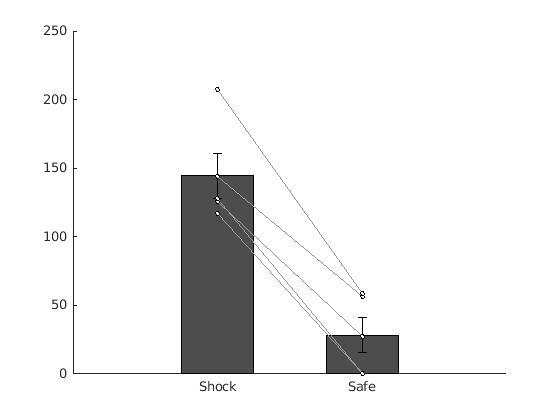

figure
%PlotErrorBarN([FreezingTime.ExtinctionBlockedShock(:,1),FreezingTime.ExtinctionBlockedSafe(:,2)],0);
bar(1,nanmean(FreezingTime.ExtinctionBlockedSafe(:,2)'),'FaceColor',[0.6 0.6 1]), hold on
bar(2,nanmean(FreezingTime.ExtinctionBlockedShock(:,1)'),'FaceColor',[1 0.6 0.6])
plotSpread({FreezingTime.ExtinctionBlockedSafe(:,2);FreezingTime.ExtinctionBlockedShock(:,1)},'distributionColors',[ 0 0 0;0 0 0],'MarkerSize',10)

set(gca,'XTick',[1,2],'XTickLabel',{'Shock','Safe'})

Look at risk assesmment behaviour

clear ZoneTime
Files=PathForExperimentsEmbReact('TestPre_EyeShock');
tps=[0:0.01:4];
for mm=1:length(Files.path)
    RiskAsess.TestPre.ToSafeMov{mm}=[];RiskAsess.TestPre.ToSafeType{mm}=[];
    RiskAsess.TestPre.ToShockMov{mm}=[];RiskAsess.TestPre.ToShockType{mm}=[];
    for c=1:4
        cd(Files.path{mm}{c})
        clear Behav
        load('behavResources_SB.mat')
        for type=1:3
            RiskAsess.TestPre.ToSafe{type}(mm,c)=sum(Behav.RAUser.ToSafe>=type-1);
            RiskAsess.TestPre.ToShock{type}(mm,c)=sum(Behav.RAUser.ToShock>=type-1);
        end
        % Shock
        if not(isempty(Start(Behav.RAEpoch.ToShock)))
            SmooDiffLinDist=tsd(Range(Behav.LinearDist),[0;diff(runmean(Data(Behav.LinearDist),20))]);
            tpsout=FindClosestZeroCross(Start(Behav.RAEpoch.ToShock),SmooDiffLinDist,1);
            for t=1:length(tpsout)
                try
                    LitEp=intervalSet(tpsout(t)-2*1e4,tpsout(t)+2*1e4);
                    dattemp=interp1(Range(Restrict(SmooDiffLinDist,LitEp))-(tpsout(t)-2*1e4),Data(Restrict(SmooDiffLinDist,LitEp)),[0:0.01:4]*1e4);
                    RiskAsess.TestPre.ToShockMov{mm}=[RiskAsess.TestPre.ToShockMov{mm};dattemp];
                    RiskAsess.TestPre.ToShockType{mm}=[RiskAsess.TestPre.ToShockType{mm},Behav.RAUser.ToShock(t)];
                end
            end
        end
        
        % Safe
        if not(isempty(Start(Behav.RAEpoch.ToSafe)))
            SmooDiffLinDist=tsd(Range(Behav.LinearDist),[0;diff(runmean(Data(Behav.LinearDist),20))]);
            tpsout=FindClosestZeroCross(Start(Behav.RAEpoch.ToSafe),SmooDiffLinDist,-1);
            for t=1:length(tpsout)
                try
                    LitEp=intervalSet(tpsout(t)-2*1e4,tpsout(t)+2*1e4);
                    dattemp=interp1(Range(Restrict(SmooDiffLinDist,LitEp))-(tpsout(t)-2*1e4),Data(Restrict(SmooDiffLinDist,LitEp)),[0:0.01:4]*1e4);
                    RiskAsess.TestPre.ToSafeMov{mm}=[ RiskAsess.TestPre.ToSafeMov{mm};dattemp];
                    RiskAsess.TestPre.ToSafeType{mm}=[RiskAsess.TestPre.ToSafeType{mm},Behav.RAUser.ToSafe(t)];
                end
            end
        end
    end
end

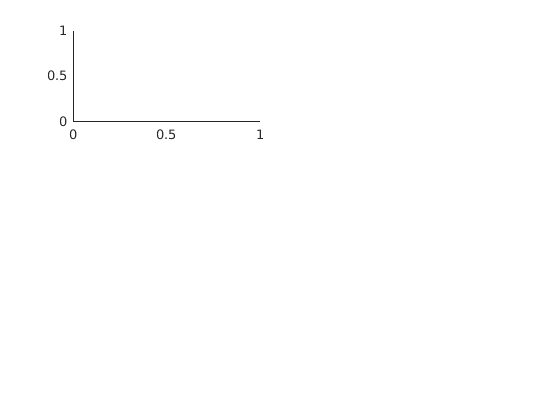

Reference to non-existent field 'TestPre'.


clear ZoneTime
Files=PathForExperimentsEmbReact('TestPost_EyeShock');
for mm=1:length(Files.path)
    for c=1:4
        cd(Files.path{mm}{c})
        clear Behav
        load('behavResources_SB.mat')
        for k=1:5
            for type=1:3
                RiskAsess.TestPost.ToSafe{type}(mm,c)=sum(Behav.RAUser.ToSafe>=type-1);
                RiskAsess.TestPost.ToShock{type}(mm,c)=sum(Behav.RAUser.ToShock>=type-1);
            end
        end
    end
end

clear ZoneTime
Files=PathForExperimentsEmbReact('UMazeCond_EyeShock');
MouseToAvoid=[560,117,431]; % mice with noisy data to exclude
Files=RemoveElementsFromDir(Files,'nmouse',MouseToAvoid);
for mm=1:length(Files.path)
    for c=1:3
        cd(Files.path{mm}{c})
        clear Behav
        load('behavResources_SB.mat')
        for k=1:5
            for type=1:3
                RiskAsess.UMAzeCond.ToSafe{type}(mm,c)=sum(Behav.RAUser.ToSafe>=type-1);
                RiskAsess.UMAzeCond.ToShock{type}(mm,c)=sum(Behav.RAUser.ToShock>=type-1);
            end
        end
    end
end

clear ZoneTime
Files=PathForExperimentsEmbReact('UMazeCondBlockedShock_EyeShock');
MouseToAvoid=[560,117,431]; % mice with noisy data to exclude
Files=RemoveElementsFromDir(Files,'nmouse',MouseToAvoid);
for mm=1:length(Files.path)
    for c=1:3
        cd(Files.path{mm}{c})
        clear Behav
        load('behavResources_SB.mat')
        for k=1:5
            for type=1:3
                RiskAsess.UMAzeCondBlockedShock.ToSafe{type}(mm,c)=sum(Behav.RAUser.ToSafe>=type-1);
                RiskAsess.UMAzeCondBlockedShock.ToShock{type}(mm,c)=sum(Behav.RAUser.ToShock>=type-1);
            end
        end
    end
end

clear ZoneTime
Files=PathForExperimentsEmbReact('UMazeCondBlockedSafe_EyeShock');
MouseToAvoid=[560,117,431]; % mice with noisy data to exclude
Files=RemoveElementsFromDir(Files,'nmouse',MouseToAvoid);
for mm=1:length(Files.path)
    for c=1:3
        cd(Files.path{mm}{c})
        clear Behav
        load('behavResources_SB.mat')
        for k=1:5
            for type=1:3
                RiskAsess.UMAzeCondBlockedSafe.ToSafe{type}(mm,c)=sum(Behav.RAUser.ToSafe>=type-1);
                RiskAsess.UMAzeCondBlockedSafe.ToShock{type}(mm,c)=sum(Behav.RAUser.ToShock>=type-1);
            end
        end
    end
end

figure
DurSess=3;
for type=1:3
    subplot(3,2,(type-1)*2+1)
    PlotErrorBarN([mean(RiskAsess.TestPre.ToShock{type}')/DurSess;mean(RiskAsess.TestPre.ToSafe{type}')/DurSess]',0,1);
    set(gca,'XTick',[1,2],'XTickLabel',{'To Shock','To Safe'})
    xlabel('RA/min')
    if type==1
        title('Test Pre')
    end
    subplot(3,2,(type-1)*2+2)
    PlotErrorBarN([mean(RiskAsess.TestPost.ToShock{type}')/DurSess;mean(RiskAsess.TestPost.ToSafe{type}')/DurSess]',0,1);
    set(gca,'XTick',[1,2],'XTickLabel',{'To Shock','To Safe'})
    if type==1
        title('Test Post')
    end
end



figure
DurSess=8;
for type=1:3
    subplot(3,3,(type-1)*3+1)
    PlotErrorBarN([mean(RiskAsess.UMAzeCond.ToShock{type}')/DurSess;mean(RiskAsess.UMAzeCond.ToSafe{type}')/DurSess]',0,1);
    set(gca,'XTick',[1,2],'XTickLabel',{'To Shock','To Safe'})
    xlabel('RA/min')
    if type==1
        title('UMazeCond')
    end
end

DurSess=3;
for type=1:3
    subplot(3,3,(type-1)*3+2)
    PlotErrorBarN([mean(RiskAsess.UMAzeCondBlockedShock.ToShock{type}')/DurSess;mean(RiskAsess.UMAzeCond.ToSafe{type}')/DurSess]',0,1);
    set(gca,'XTick',[1,2],'XTickLabel',{'To Shock','To Safe'})
    xlabel('RA/min')
    if type==1
        title('UMAzeCondBlockedShock')
    end
end

DurSess=3;
for type=1:3
    subplot(3,3,(type-1)*3+3)
    PlotErrorBarN([mean(RiskAsess.UMAzeCondBlockedSafe.ToShock{type}')/DurSess;mean(RiskAsess.UMAzeCond.ToSafe{type}')/DurSess]',0,1);
    set(gca,'XTick',[1,2],'XTickLabel',{'To Shock','To Safe'})
    xlabel('RA/min')
    if type==1
        title('UMAzeCondBlockedSafe')
    end
end

